# 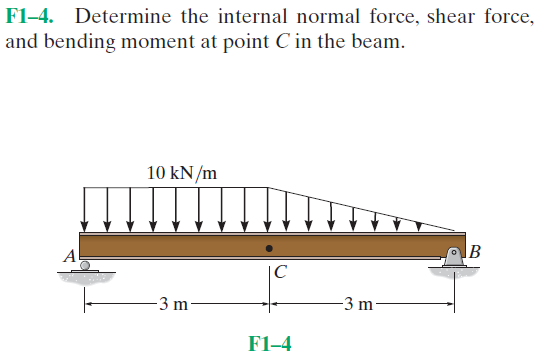

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

wf = findpoly(1, 'thru', [3*u.m -10*u.kN/u.m], [6*u.m 0]);
b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('distributed', 'force', -10*u.kN/u.m, [0 3]*u.m);
b = b.add('distributed', 'force', wf, [3 6]*u.m, [false true]);
b.L = 6*u.m;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(10\,x^{3}-110\,x^{2}\,m+1827\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{\left(x-6\,m\right)\,\left(2\,x^{4}-48\,x^{3}\,m+222\,x^{2}\,m^{2}+792\,x\,m^{3}+81\,m^{4}\right)}{72\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{40\,x^{3}-330\,x^{2}\,m+1827\,m^{3}}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -\frac{-10\,x^{4}+240\,x^{3}\,m-1530\,x^{2}\,m^{2}+1080\,x\,m^{3}+4671\,m^{4}}{72\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(2\,x-11\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{5\,\left(x-6\,m\right)\,\left(2\,x^{2}-24\,x\,m+9\,m^{2}\right)}{18}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(4\,x-11\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{5\,\left(2\,x^{2}-24\,x\,m+51\,m^{2}\right)}{6}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -10\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{10\,\left(x-6\,m\right)}{3}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = \frac{55}{2}\,\mathrm{kN}$$

Rb = r.Rb %#ok

$$Rb = \frac{35}{2}\,\mathrm{kN}$$

clear Ra Rb;

# shear and moment diagram

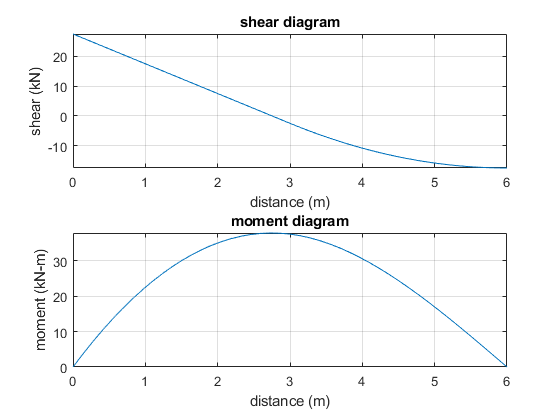

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

setassum(old_assum);
clear old_assum;